% jan 2016

% EXERCISE 2

## PLANAR 3R

syms q1 real
syms q2 real
syms q3 real

syms l1 real
syms l2 real
syms l3 real

alpha = [0 0 0];
a=[l1 l2 l3];
d=[0 0 0];
theta=[q1 q2 q3];

table=[alpha',a',d',theta']

$$table = \left(\begin{array}{cccc} 0 & l_{1} & 0 & q_{1}\\ 0 & l_{2} & 0 & q_{2}\\ 0 & l_{3} & 0 & q_{3} \end{array}\right)$$

%plot the robot

%Note: it has different format respect to Sveva's DHMatrix function
l_1 = 0.1;
l_2 = 0.1;
l_3 = 0.1;

a_no_sym = double(subs(a, {l1,l2,l3}, {l_1,l_2,l_3}));
alpha_no_sym = alpha;
d_no_sym = d;
theta_no_sym = double(subs(theta, {q1,q2,q3}, {0, 0,0}));

DHTable=[a_no_sym', alpha_no_sym',d_no_sym',theta_no_sym']

DHTable =     0.1000         0         0         0
    0.1000         0         0         0
    0.1000         0         0         0


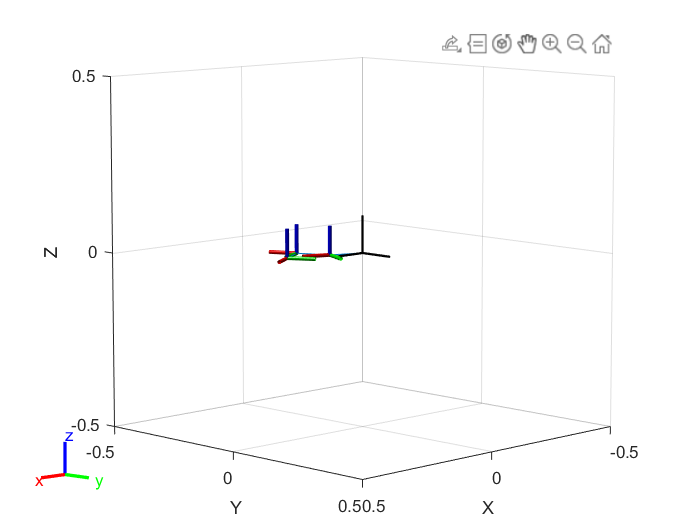

joints = 'RRR';
robot_model = build_robot_model(joints, DHTable);

%config = homeConfiguration(robot_model)%build_configuration(robot_model, array_joint_values);

show(robot_model, randomConfiguration(robot_model));%config);

% KINEMATIC
fprintf("______________________________Kinematic___________________________________\n")
[T, A] = DHMatrix(table);
A0_1=A{1};
A1_2=A{2};
A2_3=A{3};
T;
f_r_3D = get_f_r(T); %(X Y Z PHI)

f_r = [f_r_3D(1); f_r_3D(2); f_r_3D(4)]

% DINAMIC
fprintf("______________________________Diff___________________________________\n")
J = simplify(jacobian(f_r, [q1 q2 q3]))

l1=0.5;
l2=0.5;
l3=0.5;
J = simplify(subs(J)) % sub l1 l2 l3

q0 = deg2rad([30 30 120])

%A
J_0 = subs(J, {q1,q2,q3}, q0)
rank_J_0 = rank(J_0)

% since the rank of the jacobian in q0 is maximum (3), all velocities are
% feasible instantaneously, so v can be performed 
vx=0;
vy=1;
wz=0;
v = [vx;vy;wz]

%[v w]' = J q_dot
% B = AX
A = J_0;
B = v;
q_dot = linsolve(A,B)
q_dot_ = double(q_dot)

% the solution is unique since J_0 has full rank

% B
% Mapping joint force and cartesian force:
% q_torques = J' * F

J_0_T = J_0'
rank_J_0_T = rank(J_0_T)

F_e = [-5;0];
%we considers a zero momennt applied on the end effector (M_z = 0)
M_z = 0;
F_e = [F_e; M_z]

%The joint torques applied by Fe is the following:
q_torque_e = J_0_T * F_e
    q_torque_e_ = double(q_torque_e)

%so, the robot to remain in static conditions must apply an opposite joint
%torques
q_torque = -q_torque_e
    q_torque_ = double(q_torque)

% the solution is unique since J_0_T has full rank

% EXERCISE 3

## A

% cartesian path
syms t
px_t = 0.15+0.05*cos(5*pi*t);
py_t = 0.05*sin(5*pi*t);
p_t=[px_t; py_t]
p_t_dot = diff(p_t, t)

t=0.2
p_02 = simplify(subs(p_t))
p_02_dot = simplify(subs(p_t_dot))
    double(p_02_dot)

% planar 2R
syms q1 q2 dq1 dq2 'real'

% length l
l1=0.1
l2=0.2

% p in planar 2R
r=[l1*cos(q1)+l2*cos(q1+q2);
    l1*sin(q1)+l2*sin(q1+q2)]

% jacobian
J=jacobian(r,[q1 q2])

% time derivative of the Jacobian
Jder=[-l1*cos(q1)*dq1-l2*cos(q1+q2)*(dq1+dq2) -l2*cos(q1+q2)*(dq1+dq2);
    -l1*sin(q1)*dq1-l2*sin(q1+q2)*(dq1+dq2) -l2*sin(q1+q2)*(dq1+dq2)];


%% Inverse kinematic
% x of p and y of p
px= p_02(1)

$$px = \frac{1}{10}$$

double(p_02(1))

ans = 0.1000


py= p_02(2)

$$py = 0$$

double(p_02(2))

ans = 0


%%  q2
% second joint computations
c2=(px^2+py^2-l1^2-l2^2)/(2*l1*l2);
    s2pos=simplify(sqrt(1-c2^2));  
    %other solution: -sqrt(1-c2^2)
    s2neg= simplify(-sqrt(1-c2^2));  

%% q1
% first joint computations
detM=l1^2+l2^2+2*l1*l2*c2;

% positive solution of q1
s1pos=simplify((py*(l1+l2*c2)-px*l2*s2pos)/detM);
c1pos=simplify((px*(l1+l2*c2)+py*l2*s2pos)/detM);

% negative solution of q1
s1neg=simplify((py*(l1+l2*c2)-px*l2*s2neg)/detM);
c1neg=simplify((px*(l1+l2*c2)+py*l2*s2neg)/detM);

% output positive
fprintf("Positive configuration\n")

Positive configuration


q01p=simplify(atan2(s1pos,c1pos));
q02p=simplify(atan2(s2pos,c2));
q0p=[q01p; q02p]

$$q0p = \left(\begin{array}{c} \pi \\ \pi \end{array}\right)$$

    double(q0p)

ans =     3.1416
    3.1416



fprintf("Negative configuration\n")

Negative configuration


% output negative
q01n=simplify(atan2(s1neg,c1neg));
q02n=simplify(atan2(s2neg,c2));
q0n =[q01n;q02n]

$$q0n = \left(\begin{array}{c} \pi \\ \pi \end{array}\right)$$

    double(q0n)

ans =     3.1416
    3.1416


%% calculate joint velocity in both confinguration with p_02_dot end-effector velocity

% At Positive configuration
q1 = q01p;
q2 = q02p;

J_pos = simplify(subs(J))

$$J\_pos = \left(\begin{array}{cc} 0 & 0\\ \frac{1}{10} & \frac{1}{5} \end{array}\right)$$

    double(J_pos)

ans =          0         0
    0.1000    0.2000


    
% r_dot = J*q_dot
% q_dot = inv(J*r_dot)
%q_pos_dot = double(inv(J_pos) * p_02_dot)
q_pos_dot = pinv(J_pos) * p_02_dot

$$q\_pos\_dot = \left(\begin{array}{c} -\frac{\pi }{2}\\ -\pi \end{array}\right)$$

    double(q_pos_dot)

ans =    -1.5708
   -3.1416


    
    
% At Negative configuration
q1 = q01n;
q2 = q02n;

J_neg = simplify(subs(J))

$$J\_neg = \left(\begin{array}{cc} 0 & 0\\ \frac{1}{10} & \frac{1}{5} \end{array}\right)$$

    double(J_neg)

ans =          0         0
    0.1000    0.2000


% r_dot = J*q_dot
% q_dot = inv(J*r_dot)
%q_pos_dot = double(inv(J_neg) * p_02_dot)
q_neg_dot = pinv(J_neg) * p_02_dot

$$q\_neg\_dot = \left(\begin{array}{c} -\frac{\pi }{2}\\ -\pi \end{array}\right)$$

    double(q_neg_dot)

ans =    -1.5708
   -3.1416


    
% in this case, since J is singular we have an infinite number of
% solutions
% The solution with the minimum norm is the one above obtained using
% pseudoinverse

% the others infinite solutions can be obtained using "Teorema di struttura
% delle soluzioni di un sistema lineare"
%{
    A*X = b
    The solutions X of the system can be written as:
        X = X0 + alpha*null(A)
    Where 
        X0 is a solution, obtained for example by pseudo-inverse
        alpha = real value
        null(A) = null space (kernel)
%}

q_dot__X0 = pinv(J_pos) * p_02_dot;
null_space = null(J_pos);
syms alpha
q_dot__X = q_dot__X0 + alpha*null_space 

$$q\_dot\_\_X = \left(\begin{array}{c} -2\,\alpha -\frac{\pi }{2}\\ \alpha -\pi \end{array}\right)$$

b = [0; -pi/4]

b =          0
   -0.7854


A = J_pos 

$$A = \left(\begin{array}{cc} 0 & 0\\ \frac{1}{10} & \frac{1}{5} \end{array}\right)$$

%x = linsolve(A,b)

n = null(A)

$$n = \left(\begin{array}{c} -2\\ 1 \end{array}\right)$$

## B

% control law
kp=10*eye(2)
q_t_dot = simplify(inv(J)*(p_t_dot+kp*(p_t-r)))

t=1.8
q1 = -pi/2;
q2 = pi/2;
q_a_dot = simplify(subs(q_t_dot))
    double(q_a_dot)
    
J_a = subs(J)
p_a_dot = J_a * q_a_dot
    double(p_a_dot)

p_a_dot_norm = norm(p_a_dot)
    double(p_a_dot_norm)
    
p_a_dot_direct = p_a_dot / p_a_dot_norm
    double(p_a_dot_direct)
    
p_a_dot_check = p_a_dot_norm * p_a_dot_direct